# 4D Examples

This example demonstrates the use of regularizeNd with a 4D input and 1D output dataset. Note, that selecting the smoothness isn't always obvious until you have gained experience using regularizeNd. Often the best choice is to change the smoothness by factors of 10 until you have reached the smooth hyper surface that you want or reduce the smoothness until you have reached the fidelity you want. Even if my first guess of the smoothness is adequate, I change the smoothness by factors of 10 until it isn't smooth to see the effect of the smoothness parameter.

Note this example has 30,240 grid points. This means the linear system solved, x = A\y, has 250,505 rows and 30,240 columns with 2,539,252 nonzero elements in A. This solves on my laptop in 6 seconds.

clc; clear; close all;

## Load Data

convert to double because I saved them as single to save space.

load('dataset_4d_1.mat')

% inputs.
x1 = double(x1);
y1 = double(y1);
z1 = double(z1);
t1 = double(t1);

% ouput
w1 = double(w1);

## Look at the Input and Output Vectors

The main point is there is a lot of points. The input space is well filled. I am not implying good fill is necessary. Sometimes it is necessary. Sometimes it isn't. The fill need in the input space depends on each case. 

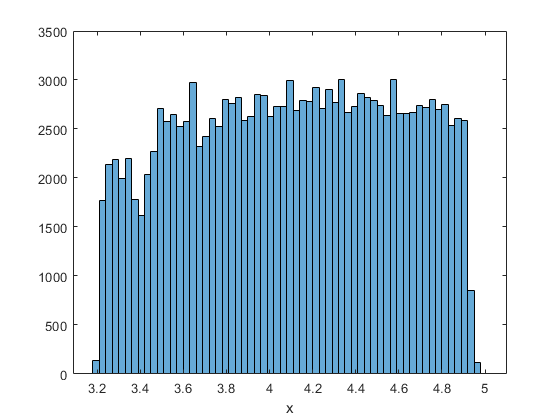

figure;
histogram(x1)
xlabel('x');

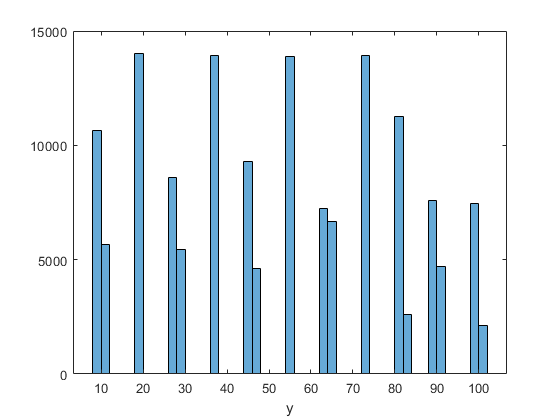

figure;
histogram(y1)
xlabel('y');

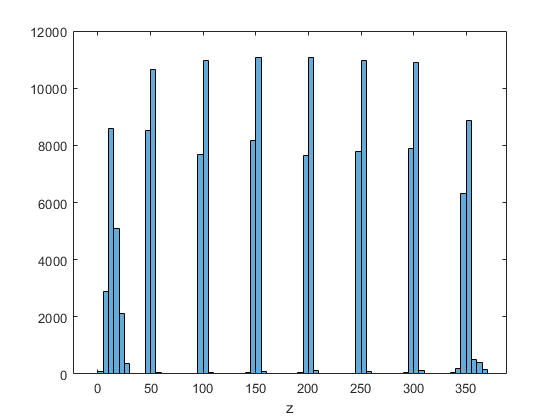

figure;
histogram(z1)
xlabel('z');

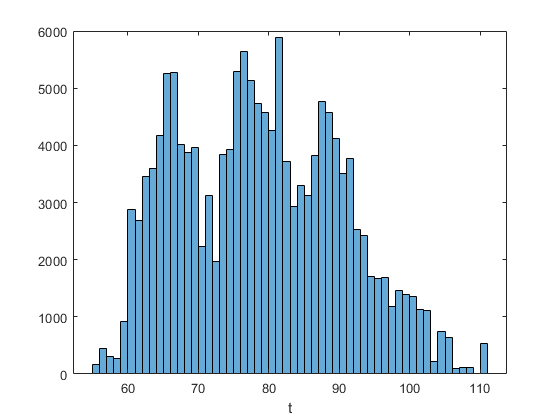

figure;
histogram(t1)
xlabel('t');

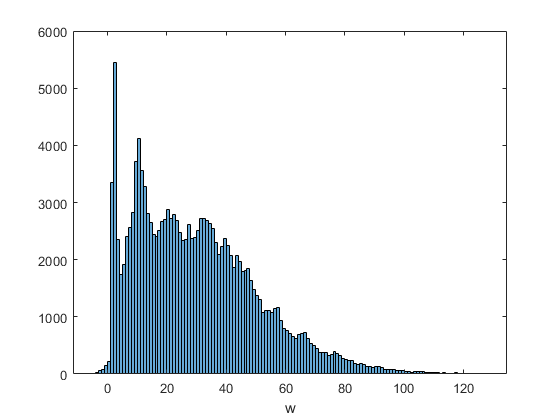


figure
histogram(w1)
xlabel('w');

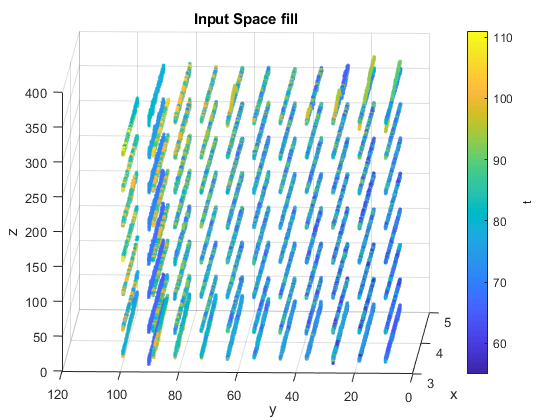


figure;
scatter3(x1,y1,z1, [], t1, '.');
view(-87.2, 12.4);
xlabel('x'); ylabel('y'); zlabel('z');
h = colorbar;
ylabel(h, 't');
title('Input Space fill');

## Creating the regularized hypersurface

Note with regularizeNd, the grid vectors must always span the input data. The reason for this is that calculating the weights for a given query point is well defined for interpolation and it not well defined for extrapolation. Understand though, that the fact that the grid vectors can far exceed the expanses of the fitted data and the fitted surface is guaranteed to change close to linearly far away from fitted data is of great advantage over other fitting technieques. It allows extrapolation away from the fitted data in a known way. In polynomial fitting, there is no guarantee how the polynomial will behave outside of the test data set.

smoothness =     0.0001    0.0010    0.0010    0.0100


Elapsed time is 6.866527 seconds.


smoothness = 1.0000e-03

Elapsed time is 6.677745 seconds.


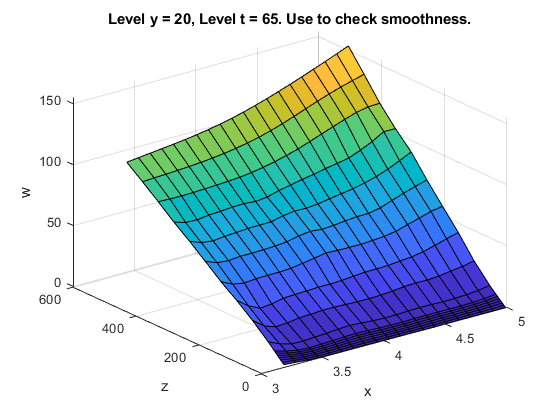

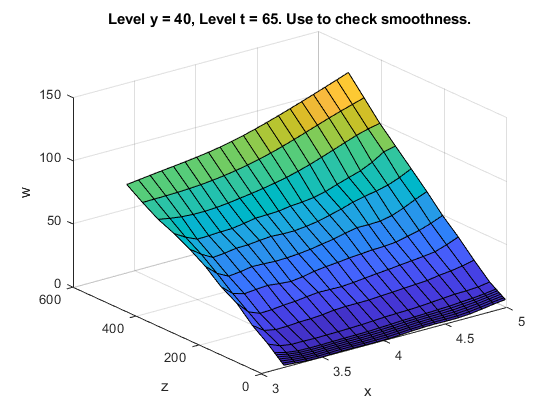

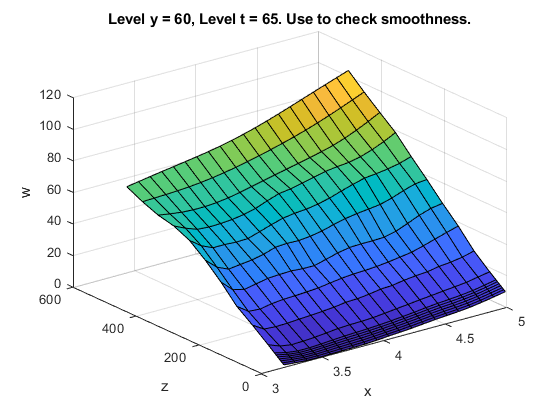

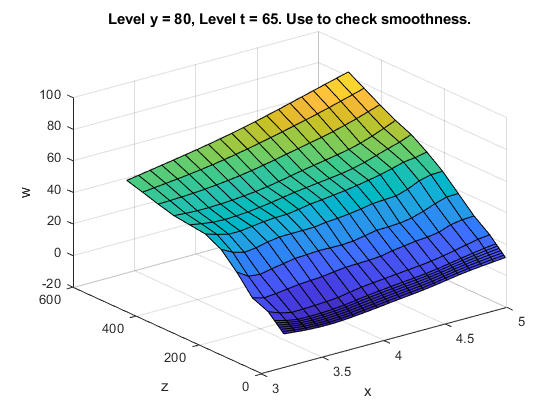

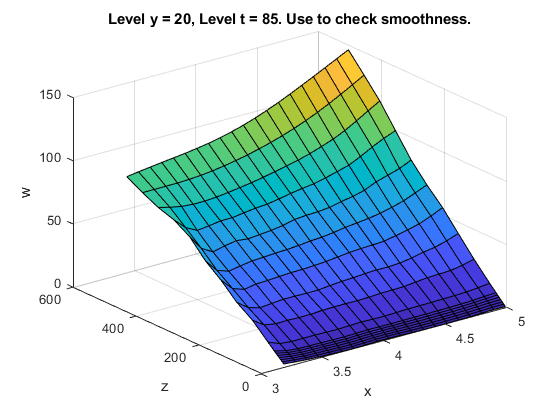

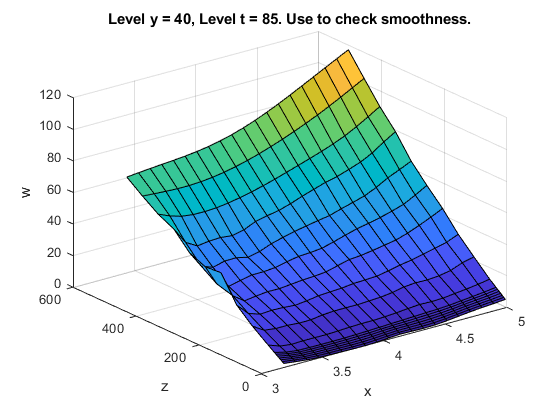

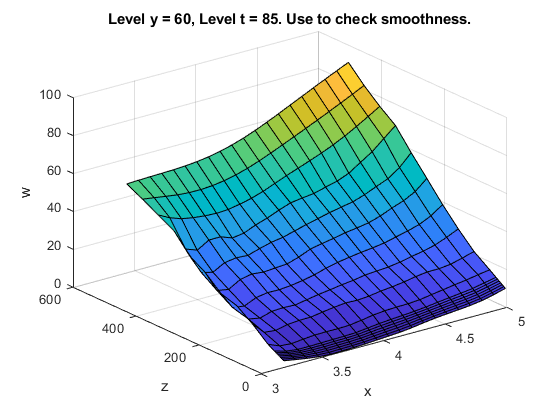

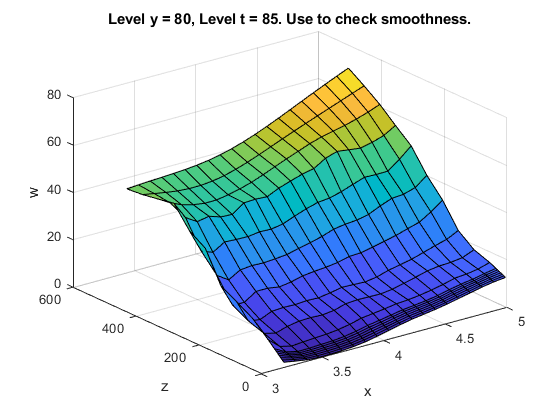

% setup the grid points
xGrid = linspace(min(x1), max(x1), 20);
yGrid = 0:10:110;
zGrid = [-0.11 0:5:30 50:50:500];
tGrid = [50 65 75 80 90 100 115];
gridPoints = {xGrid, yGrid, zGrid, tGrid};

% Setup to loop
smoothness = [1e-4, 1e-3, 1e-3, 1e-2];
% smoothness = [7e-3, 1e-2, 8e-3, 1e-1]; % better values
whileFlag = true;
tPlotLevels = [65 85];
yPlotLevels = [20 40 60 80];
gridForPlots = cell(4,1);
[gridForPlots{:}] = ndgrid(xGrid, yPlotLevels, zGrid, tPlotLevels);
surfaceHandles = nan(length(tPlotLevels), length(yPlotLevels));

while whileFlag
    display(smoothness);
    
    % Calculate regularized surface and time it
    tic;
    wGrid = regularizeNd([x1,y1,z1,t1], w1, gridPoints, smoothness, 'linear');
    toc;
    
    % create the griddedInterpolant function
    wFunction = griddedInterpolant(gridPoints, wGrid, 'linear');
    
    % calculate values for the plots
    wPlot = wFunction(gridForPlots{:});
    
    % create the plot levels. Often I use a lot more than 8 levels. Often,
    % I will put them on the same figure/axes. However, for simplicity and
    % clarity, I left them as individual figures here.
    for iT = 1:length(tPlotLevels)
        for iY = 1:length(yPlotLevels)
            if ishghandle(surfaceHandles(iT,iY))
                 set(surfaceHandles(iT,iY), 'Zdata', squeeze(wPlot(:,iY,:,iT))');
            else
                figure;
                surfaceHandles(iT,iY) = surf(xGrid, zGrid, squeeze(wPlot(:,iY,:,iT))');
                xlabel('x');ylabel('z'); zlabel('w');
                title(sprintf('Level y = %g, Level t = %g. Use to check smoothness.', yPlotLevels(iY), tPlotLevels(iT)));
            end
            
        end
    end
    
    % Ask for a new smoothness
    answer = input('Enter a new smoothness to recaculate surface.');
    
    % parse the answer
    if isempty(answer)
        % Do nothing
    elseif any(answer == -1)
        whileFlag = false;
    elseif any(answer<0)
        warning('Negative values of smoothness not excepted. No changes made.');
    else
        if any(length(answer) == [1 length(gridPoints)])
            smoothness = answer;
        else
            warning('smoothness must be either scalar or have same number elements as the length of gridPoints. No change to smoothness was made.');
        end
    end
end

## Look at the residuals

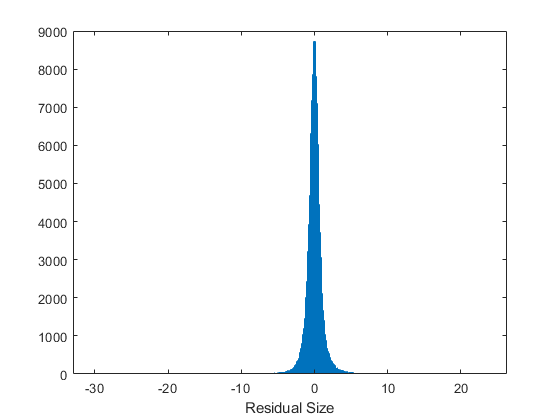

% calculate the residuals
residualsAbsolute = w1 - wFunction(x1,y1,z1,t1);

figure;
histogram(residualsAbsolute, 'FaceColor', 'auto', 'EdgeColor', 'auto')
xlabel('Residual Size');